# 第二周作业模板：配电网储能选址定容优化 (Big-M 线性化 + LinDistFlow) 与交流潮流验证

课程名称：《储能优化配置与调度技术》课程设计

## 0. 模板使用说明与核心数学模型

**使用说明**：

- 请将本模板复制到 `ESS-Course-Submissions` 仓库下你的 【学号_姓名拼音】 文件夹中；

- 重命名为 【姓名拼音_学号_Week2.mlx】，并修改第 2 节中的 `Stu_ID` 为本人真实 9 位学号；

- 运行完毕后将自动在当前目录下生成标准化评测文件 `result_summary.mat`，请勿修改第 10 节结构体字段名。

**核心数学模型**：

**1) 全生命周期年综合费用目标函数**：


$$\min F = C_{\mathrm{inv}}^{\mathrm{ann}} + C_{\mathrm{om}}^{\mathrm{ann}} + C_{\mathrm{grid}}^{\mathrm{ann}} = \mathrm{CRF} \sum_{i\in\Omega_{\mathrm{cand}}} \left( c_P P_i^{\mathrm{rated}} + c_E E_i^{\mathrm{rated}} \right) + \sum_{i\in\Omega_{\mathrm{cand}}} c_{\mathrm{om}} P_i^{\mathrm{rated}} + D_{\mathrm{days}} \sum_{t=1}^{T} \lambda_t P_{\mathrm{grid},t} \Delta t$$


**2) 双线性非凸项** $\mathrm{SoC}_{i,t} \cdot E_i^{\mathrm{rated}}$ **的离散档位编码与大M法（McCormick 包络）线性化**：

引入离散容量选择二进制变量 $w_{i,k} \in \{0,1\}$ 与连续辅助变量 $\delta_{i,k,t} = \mathrm{SoC}_{i,t} \cdot w_{i,k}$，满足：


$$\sum_{k=1}^{K} w_{i,k} = z_i, \quad E_i^{\mathrm{rated}} = \sum_{k=1}^{K} w_{i,k} E_k^{\mathrm{opt}}, \quad P_i^{\mathrm{rated}} = \sum_{k=1}^{K} w_{i,k} P_k^{\mathrm{opt}}$$



$$\mathrm{SoC}_{\min} \cdot w_{i,k} \le \delta_{i,k,t} \le \mathrm{SoC}_{\max} \cdot w_{i,k}$$



$$\mathrm{SoC}_{i,t} - \mathrm{SoC}_{\max}\left(1 - w_{i,k}\right) \le \delta_{i,k,t} \le \mathrm{SoC}_{i,t} - \mathrm{SoC}_{\min}\left(1 - w_{i,k}\right)$$



$$\sum_{k=1}^{K} E_k^{\mathrm{opt}} \left( \delta_{i,k,t} - \delta_{i,k,t-1} \right) = \left( \eta_{\mathrm{ch}} P_{i,t}^{\mathrm{ch}} - \frac{1}{\eta_{\mathrm{dis}}} P_{i,t}^{\mathrm{dis}} \right) \Delta t$$


**3) 配电网 LinDistFlow 线性化潮流方程与工程电压安全裕度约束**：


$$U_{j,t}^{\mathrm{Lin}} = U_{i,t}^{\mathrm{Lin}} - 2\left( r_{ij} P_{ij,t} + x_{ij} Q_{ij,t} \right), \quad \left(V_{\min}^{\mathrm{Lin}}\right)^2 \le U_{i,t}^{\mathrm{Lin}} \le \left(V_{\max}^{\mathrm{Lin}}\right)^2$$


clear; clc; close all;
yalmip('clear');
%----------------------------请修改地址------------------------------
addpath("D:\Research\EnergyStorageCourse\ESS-Course-Materials\cases\")

%-------------------------------------------------------------------

## 1. 自动检测算例库是否已在 MATLAB 搜索路径中

if ~exist('case_nongcun.m', 'file')
    % 若不在路径中，弹窗提示学生选择一次本地的 ESS-Course-Materials/cases 文件夹
    case_dir = uigetdir(pwd, '请选择教学资源库中的 cases 文件夹路径');
    addpath(case_dir);
end

## 2. 学号映射与网络参数读取

**【学生修改区】**：请将下方 `Stu_ID` 修改为你本人的 9 位学号！

Stu_ID  = 209230738;
XY      = mod(Stu_ID, 100);
X_digit = floor(XY / 10);
Y_digit = mod(XY, 10);
alpha   = 1 + 0.002 * XY;

if ismember(Y_digit, [0, 1, 2, 3])
    case_name = 'case_nongcun';
elseif ismember(Y_digit, [4, 5, 6])
    case_name = 'case_chengshi_A';
else
    case_name = 'case_kaifaqu_A';
end
mpc = loadcase(case_name);
load('profiles_24h.mat');

if ismember(X_digit, [0, 1, 2])
    cand_buses = [4, 9, 14];
elseif ismember(X_digit, [3, 4, 5])
    cand_buses = [5, 11, 16];
else
    cand_buses = [6, 13, 17];
end
N_cand = length(cand_buses);

## 3. 规划经济参数与储能离散容量档位

为补偿 LinDistFlow 忽略支路电流平方项导致的电压高估偏差，收紧优化电压下限至 $V_{\min}^{\mathrm{Lin}} = 0.960\;\mathrm{p.u.}$。

P_opt_MW  = [1, 2, 3, 4, 5]; % 离散功率档位 (MW)
E_opt_MWh = [1, 2, 3, 4, 5]; % 离散容量档位 (MWh)
K = length(E_opt_MWh);

eta_ch  = 0.90;
eta_dis = 0.95;
SoC_min = 0.20;
SoC_max = 0.80;
SoC_0   = 0.50;

c_P    = 0.08 * 1e6;   % 单位功率投资成本: 80,000 元/MW
c_E    = 0.55 * 1e6;   % 单位能量投资成本: 550,000 元/MWh
c_om   = 200 * 1e3;    % 单位功率年运维成本: 200,000 元/(MW*年)
Y_life = 20;           % 规划年限: 20 年
d_rate = 0.05;         % 贴现率: 5%
CRF    = (d_rate * (1 + d_rate)^Y_life) / ((1 + d_rate)^Y_life - 1);
D_days = 365;

V_min_Lin = 0.960;
V_max_Lin = 1.050;

## 4. 配电网拓扑与负荷标幺值计算

Sbase = mpc.baseMVA;
N_bus = size(mpc.bus, 1);
N_br  = size(mpc.branch, 1);
fbus  = mpc.branch(:, 1);
tbus  = mpc.branch(:, 2);
r_br  = mpc.branch(:, 3);
x_br  = mpc.branch(:, 4);

Pd_pu = (mpc.bus(:, 3) * alpha / Sbase) * load_curve_pu';
Qd_pu = (mpc.bus(:, 4) * alpha / Sbase) * load_curve_pu';

## 5. 声明 YALMIP 决策变量

保留 $\mathrm{SoC}_{i,t}$ 为决策变量，引入档位二进制变量 $w_{i,k}$ 与辅助变量 $\delta_{i,k,t}$。

z        = binvar(N_cand, 1, 'full');    % 候选节点选址二进制变量 z_i
w        = binvar(N_cand, K, 'full');    % 容量档位选择二进制变量 w_{i,k}
SoC      = sdpvar(N_cand, T, 'full');    % 储能荷电状态 SoC_{i,t}
delta    = sdpvar(N_cand, K, T, 'full'); % Big-M 辅助变量 \delta_{i,k,t} = SoC_{i,t} * w_{i,k}
P_ch_MW  = sdpvar(N_cand, T, 'full');    % 充电功率 (MW)
P_dis_MW = sdpvar(N_cand, T, 'full');    % 放电功率 (MW)
u_ch     = binvar(N_cand, T, 'full');    % 充放电互斥二进制变量

U_lin     = sdpvar(N_bus, T, 'full');    % LinDistFlow 节点电压平方 (p.u.^2)
P_br      = sdpvar(N_br,  T, 'full');    % 支路有功潮流 (p.u.)
Q_br      = sdpvar(N_br,  T, 'full');    % 支路无功潮流 (p.u.)
P_grid_pu = sdpvar(1,     T, 'full');    % 关口购电有功功率 (p.u.)
Q_grid_pu = sdpvar(1,     T, 'full');    % 关口注入无功功率 (p.u.)

## 6. 构建储能选址定容与大M法线性化约束

Constraints = [];
P_rated     = w * P_opt_MW';
E_rated     = w * E_opt_MWh';
P_rated_MW  = P_rated;
E_rated_MWh = E_rated;
P_max_bound = max(P_opt_MW);

for idx = 1:N_cand
    Constraints = [Constraints, sum(w(idx, :)) == z(idx)];
    Constraints = [Constraints, SoC_min <= SoC(idx, :) <= SoC_max];
    Constraints = [Constraints, SoC(idx, T) == SoC_0];
    
    Constraints = [Constraints, 0 <= P_ch_MW(idx, :)  <= P_rated_MW(idx)];
    Constraints = [Constraints, 0 <= P_dis_MW(idx, :) <= P_rated_MW(idx)];
    Constraints = [Constraints, P_ch_MW(idx, :)  <= u_ch(idx, :) * P_max_bound];
    Constraints = [Constraints, P_dis_MW(idx, :) <= (1 - u_ch(idx, :)) * P_max_bound];
    
    % 【TODO 1】请核对并补全双线性乘积项 \delta_{i,k,t} = SoC_{i,t} * w_{i,k} 的四条大M法线性化不等式：
    for k = 1:K
        d_vec = reshape(delta(idx, k, :), 1, T);
        Constraints = [Constraints, SoC_min * w(idx, k) <= d_vec <= SoC_max * w(idx, k)];
        Constraints = [Constraints, SoC(idx, :) - SoC_max * (1 - w(idx, k)) <= d_vec <= ...
            SoC(idx, :) - SoC_min * (1 - w(idx, k))];
    end
    
    % 【TODO 2】请核对并补全线性化后的时序能量守恒递推方程：
    for t = 1:T
        if t == 1
            E_prev = E_opt_MWh * (SoC_0 * w(idx, :))';
        else
            E_prev = E_opt_MWh * reshape(delta(idx, :, t - 1), K, 1);
        end
        E_curr = E_opt_MWh * reshape(delta(idx, :, t), K, 1);
        Constraints = [Constraints, E_curr - E_prev == ...
            eta_ch * P_ch_MW(idx, t) - P_dis_MW(idx, t) / eta_dis];
    end
end

## 7. 构建 LinDistFlow 线性潮流约束

A_from  = sparse(fbus, 1:N_br, 1, N_bus, N_br);
A_to    = sparse(tbus, 1:N_br, 1, N_bus, N_br);
A_cand  = sparse(cand_buses, 1:N_cand, 1, N_bus, N_cand);
A_slack = sparse(1, 1, 1, N_bus, 1);

Constraints = [Constraints, A_to * P_br - A_from * P_br + A_slack * P_grid_pu + ...
    A_cand * ((P_dis_MW - P_ch_MW) / Sbase) == Pd_pu];
Constraints = [Constraints, A_to * Q_br - A_from * Q_br + A_slack * Q_grid_pu == Qd_pu];
Constraints = [Constraints, U_lin(1, :) == 1.0];
Constraints = [Constraints, (V_min_Lin^2) <= U_lin(2:end, :) <= (V_max_Lin^2)];

% 【TODO 3】请核对并补全 LinDistFlow 支路电压平方降落方程：
for b = 1:N_br
    Constraints = [Constraints, U_lin(tbus(b), :) == U_lin(fbus(b), :) - ...
        2 * (r_br(b) * P_br(b, :) + x_br(b) * Q_br(b, :))];
end

## 8. 定义年综合费用目标函数并调用 MATLAB 原生求解器 (intlinprog)

任务四选址定容模型为混合整数线性规划（MILP），默认调用 MATLAB Optimization Toolbox 原生 `intlinprog` 求解。为防止路径中 MOSEK 的同名兼容函数 `intlinprog.m` 覆盖 MathWorks 原生函数，求解前将内置 `optim` 目录置顶。

C_inv_ann  = CRF * sum(c_P * P_rated_MW + c_E * E_rated_MWh);
C_om_ann   = sum(c_om * P_rated_MW);
C_grid_ann = D_days * sum((Sbase * P_grid_pu') .* price_MWh);
Objective  = C_inv_ann + C_om_ann + C_grid_ann;

native_optim_dir = fullfile(matlabroot, 'toolbox', 'optim', 'optim');
if exist(native_optim_dir, 'dir')
    addpath(native_optim_dir, '-begin');
end
solver_name = 'intlinprog';
ops = sdpsettings('solver', solver_name, 'verbose', 1);
ops.intlinprog.RelativeGapTolerance = 1e-6;
ops.intlinprog.AbsoluteGapTolerance = 1e-8;
sol = optimize(Constraints, Objective, ops);


找到最优解。

Intlinprog 在根节点处停止，因为目标值在最佳值的间隙容差范围内，options.RelativeGapTolerance = 1e-06。intcon 变量是容差范围内的整数，options.ConstraintTolerance = 1e-06。




if sol.problem ~= 0
    error('MILP 选址定容求解失败: %s', yalmiperror(sol.problem));
end

## 9. 基于 MATPOWER runpf 的事后交流潮流闭环验证与真实网损收益核算

V_lin_pu      = sqrt(value(U_lin));
V_ac_base     = zeros(N_bus, T);
V_ac_ess      = zeros(N_bus, T);
Ploss_ac_base = zeros(T, 1);
Ploss_ac_ess  = zeros(T, 1);
P_net_ess_MW  = value(P_dis_MW - P_ch_MW);
mpopt = mpoption('verbose', 0, 'out.all', 0);

for t = 1:T
    mpc_b = mpc;
    mpc_b.bus(:, 3) = Pd_pu(:, t) * Sbase;
    mpc_b.bus(:, 4) = Qd_pu(:, t) * Sbase;
    res_b = runpf(mpc_b, mpopt);
    V_ac_base(:, t)  = res_b.bus(:, 8);
    Ploss_ac_base(t) = sum(real(get_losses(res_b)));
    
    mpc_e = mpc_b;
    mpc_e.bus(cand_buses, 3) = mpc_e.bus(cand_buses, 3) - P_net_ess_MW(:, t);
    res_e = runpf(mpc_e, mpopt);
    V_ac_ess(:, t)  = res_e.bus(:, 8);
    Ploss_ac_ess(t) = sum(real(get_losses(res_e)));
end

B_loss_ann           = D_days * sum((Ploss_ac_base - Ploss_ac_ess) .* price_MWh);
max_voltage_error_pu = max(max(abs(V_lin_pu - V_ac_ess)));

fprintf('\n================ 第二周：储能选址定容与交流潮流验证报告 ================\n');


================ 第二周：储能选址定容与交流潮流验证报告 ================


fprintf('学号: %d | 算例: %s | 求解器: %s\n', Stu_ID, case_name, solver_name);

学号: 209230738 | 算例: case_kaifaqu_A | 求解器: intlinprog


for idx = 1:N_cand
    fprintf('候选节点 %2d: 选址状态 z=%d | 额定功率 = %d MW | 额定容量 = %d MWh\n', ...
        cand_buses(idx), round(value(z(idx))), round(value(P_rated_MW(idx))), round(value(E_rated_MWh(idx))));
end

候选节点  5: 选址状态 z=0 | 额定功率 = 0 MW | 额定容量 = 0 MWh
候选节点 11: 选址状态 z=1 | 额定功率 = 1 MW | 额定容量 = 1 MWh
候选节点 16: 选址状态 z=1 | 额定功率 = 1 MW | 额定容量 = 1 MWh


fprintf('年化投资成本: %.2f 万元 | 年运维成本: %.2f 万元 | 事后核算年降损收益: %.2f 万元\n', ...
    value(C_inv_ann) / 1e4, value(C_om_ann) / 1e4, B_loss_ann / 1e4);

年化投资成本: 10.11 万元 | 年运维成本: 40.00 万元 | 事后核算年降损收益: 0.78 万元


fprintf('LinDistFlow 最低电压: %.4f p.u. | 交流潮流真实最低电压: %.4f p.u. | 最大电压偏差: %.4f p.u.\n', ...
    min(V_lin_pu(:)), min(V_ac_ess(:)), max_voltage_error_pu);

LinDistFlow 最低电压: 0.9600 p.u. | 交流潮流真实最低电压: 0.9589 p.u. | 最大电压偏差: 0.0012 p.u.


fprintf('========================================================================\n');

## 10. 预埋标准化输出结构体与《中国电机工程学报》规范绘图（严禁修改 Result 变量名）

注意：|Result.Opt_Sites| 保存的是候选节点集合 `cand_buses` 中的序号（|1..3|），实际配电网节点编号为 `cand_buses(Result.Opt_Sites)`。

Result.StuID       = Stu_ID;                   % 学生学号
Result.Obj_Value   = value(Objective);         % 年综合费用最优值 (元)
Result.Opt_Sites   = find(round(value(z))==1); % 选址候选节点集合中的序号 (1..3，对应母线 cand_buses(Result.Opt_Sites))
Result.Opt_P_rated = value(P_rated);           % 各候选节点配置功率 (MW)
Result.Opt_E_rated = value(E_rated);           % 各候选节点配置能量 (MWh)
Result.Max_V_Err   = max_voltage_error_pu;     % LinDistFlow 与 AC 潮流最大电压误差 (p.u.)
save('result_summary.mat', 'Result');
fprintf('[OK] 标准化评测结果已自动保存至当前目录的 result_summary.mat\n');

[OK] 标准化评测结果已自动保存至当前目录的 result_summary.mat


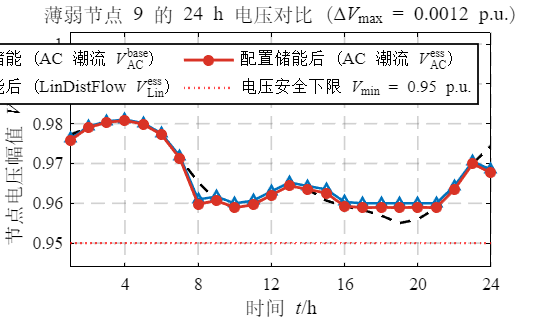


[~, worst_bus] = min(min(V_ac_base, [], 2));
fig1 = figure('Name', '薄弱节点24h电压幅值对比与线性化误差校验', 'Color', 'w', 'Position', [150, 150, 740, 440]);
if isprop(fig1, 'Theme'), theme(fig1, 'light'); end
p1 = plot(1:T, V_ac_base(worst_bus, :), '--k', 'LineWidth', 1.5); hold on;
p2 = plot(1:T, V_lin_pu(worst_bus, :), '-b^', 'LineWidth', 1.5, 'MarkerSize', 5, 'Color', [0.00, 0.45, 0.74]);
p3 = plot(1:T, V_ac_ess(worst_bus, :), '-ro', 'LineWidth', 1.7, 'MarkerSize', 5, 'MarkerFaceColor', [0.85, 0.20, 0.15], 'Color', [0.85, 0.20, 0.15]);
p4 = yline(0.95, ':r', 'LineWidth', 1.4);

y_min_plot = min([V_ac_base(worst_bus, :), V_ac_ess(worst_bus, :), 0.948]) - 0.004;
y_max_plot = max([V_lin_pu(worst_bus, :), V_ac_ess(worst_bus, :), 0.980]) + 0.022;
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'FontName', 'Times New Roman', 'FontSize', 10.5, 'LineWidth', 1.0, ...
    'Box', 'on', 'TickDir', 'in', 'XTick', 0:4:24, 'GridLineStyle', '--', 'GridAlpha', 0.3, 'GridColor', [0.4, 0.4, 0.4]);
xlim([1, T]);
ylim([y_min_plot, y_max_plot]);
xlabel('\fontname{宋体}时间 \fontname{Times New Roman}{\itt}\rm{/h}', 'FontSize', 12, 'Color', 'k', 'Interpreter', 'tex');
ylabel('\fontname{宋体}节点电压幅值 \fontname{Times New Roman}{\itV}\rm{/(p.u.)}', 'FontSize', 12, 'Color', 'k', 'Interpreter', 'tex');
title(sprintf('\\fontname{宋体}薄弱节点 \\fontname{Times New Roman}%d \\fontname{宋体}的 \\fontname{Times New Roman}24 h \\fontname{宋体}电压对比 (\\fontname{Times New Roman}\\Delta{\\itV}_{\\rm{max}} = %.4f p.u.\\fontname{宋体})', ...
    worst_bus, max_voltage_error_pu), 'FontSize', 12, 'FontWeight', 'normal', 'Color', 'k', 'Interpreter', 'tex');
leg1 = legend([p1, p2, p3, p4], { ...
    '\fontname{宋体}未配置储能 (\fontname{Times New Roman}AC \fontname{宋体}潮流 \fontname{Times New Roman}{\itV}_{\rm{AC}}^{\rm{base}}\fontname{宋体})', ...
    '\fontname{宋体}配置储能后 (\fontname{Times New Roman}LinDistFlow \fontname{Times New Roman}{\itV}_{\rm{Lin}}^{\rm{ess}}\fontname{宋体})', ...
    '\fontname{宋体}配置储能后 (\fontname{Times New Roman}AC \fontname{宋体}潮流 \fontname{Times New Roman}{\itV}_{\rm{AC}}^{\rm{ess}}\fontname{宋体})', ...
    '\fontname{宋体}电压安全下限 \fontname{Times New Roman}{\itV}_{\rm{min}} = 0.95 p.u.'}, ...
    'Location', 'north', 'NumColumns', 2, 'FontSize', 10, 'Interpreter', 'tex', 'Box', 'on');
set(leg1, 'Color', 'w', 'TextColor', 'k', 'EdgeColor', 'k');
grid on;

% 默认自动导出高质量白底 PNG (600 dpi)、矢量 PDF 与 MATLAB 源文件 FIG
exportgraphics(fig1, sprintf('Fig_Week2_Planning_%d.png', Stu_ID), 'Resolution', 600, 'BackgroundColor', 'white');
exportgraphics(fig1, sprintf('Fig_Week2_Planning_%d.pdf', Stu_ID), 'ContentType', 'vector', 'BackgroundColor', 'white');

savefig(fig1, sprintf('Fig_Week2_Planning_%d.fig', Stu_ID));